# Restricted Three Body Problem

(Created on 21 Feb 2020 18:45)

## Dependencies of the program

### Explicit

- equil_pts_position

- PlotContourEquilPoints

### Implicit

- jacobiValue3D

- Dfmatrix3D

## References for the Program

- W S koon ,MW Lo, JE Marsden, SD Ross - Dynamical Systems, the Three Body Problem and Space Mission Design (For the Lyapunoc orbits continuation Methods).

- Daniel J Grebow - Generating Periodic Orbits in the circular Restricted Three Body Problem With Applications to Lunar South Pole Coverage - MS Thesis (2006)(Insights for differential Correction andcontinuation Halo orbits)

- Srianish Vutukuri - Spacecraft Trajectory Design Techniques using Resonant Orbits (for DC and continuation)

- Thomas Pavlak - Mission Design In the Earth Moon System Transfer Trajectories and station keeping

- TM Vaquero Escribano - Poincare Sections and resonant orbits in the Restricted Three Body Problem.

## MAIN CODE

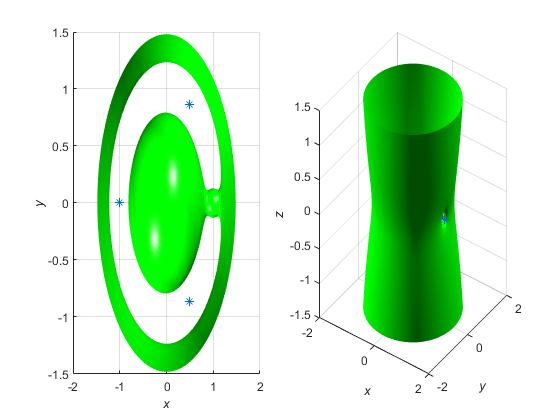

% %% --------------------------------- Mainline Program ----------------------------------------------------------------
% %% 
% clearvars;clc;close all
% 
% % Choose the problem Dimension 
% UserDat.Dimension = 3 ;%input('Give the problem dimension: ');
% % Extract the Global data
% G_var = GlobalData;
% UserDat.mu = G_var.Constants.mu;
% UserDat.EOM = G_var.IntFunc.EOM;
% UserDat.PointLoc = 1;%G_var.Constants.PointLoc;
% UserDat.NoofFam = 30;
% UserDat.CorrectionPlot = 0; 
% 
% %% Get L1 Guess and Do the Continuation
% fprintf('*******************************************\n')
% fprintf('Going for L1\n')
% fprintf('*******************************************\n')
% UserDat.PointLoc = 1;
% [XGuessL1] = InitialGuess(UserDat.PointLoc);
% if UserDat.Dimension == 3
% XGuessL1 = XGuessL1(1);
% elseif Dimension == 2
% XGuessL1 = XGuessL1(2);
% end
% % Get all the values
% [ICnTime_L(1),L1Traj] = ...
%     PerodicOrbitFamilydats(XGuessL1,UserDat.EOM,UserDat.NoofFam,UserDat.CorrectionPlot);
% 
% 
% %% Get L2 Guess and Do the Continuation
% fprintf('*******************************************\n')
% fprintf('Going for L2\n')
% fprintf('*******************************************\n')
% UserDat.PointLoc = 2;
% [XGuessL2] = InitialGuess(UserDat.PointLoc);
% if UserDat.Dimension == 3
% XGuessL2 = XGuessL2(1);
% elseif Dimension == 2
% XGuessL2 = XGuessL2(2);
% end
% [ICnTime_L(2),L2Traj] = ...
%     PerodicOrbitFamilydats(XGuessL2,UserDat.EOM,UserDat.NoofFam,UserDat.CorrectionPlot);
figure()
PlotContourEquilPoints('3DSurface')

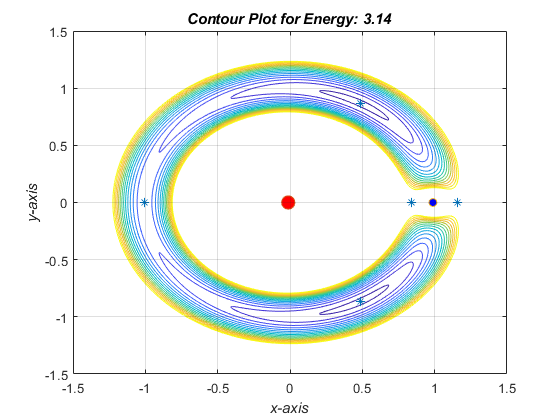

figure()
PlotContourEquilPoints('2DContour')

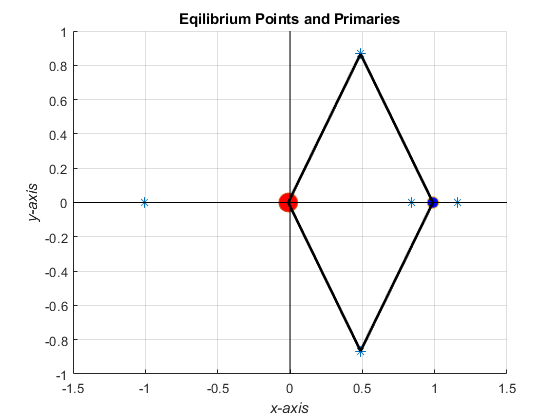

figure()
PlotContourEquilPoints('EquilPointsNPrim')

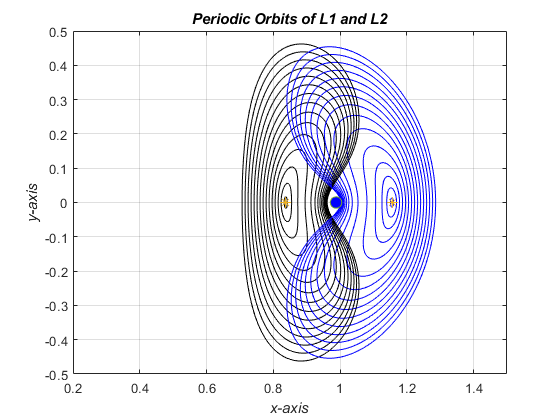

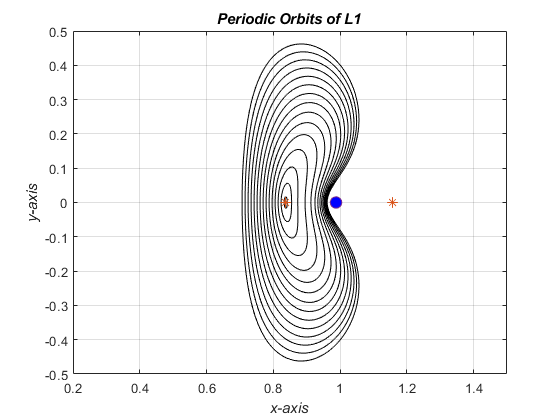

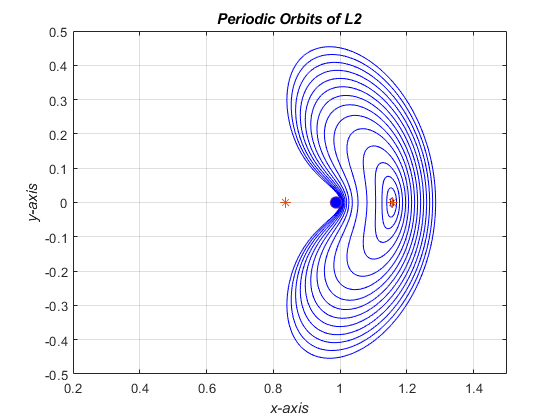

LyapunovPlotter